# Параметры системы


clear all
l1 = 0.24; % m length of the first link
l2 = 1.5; % m length of the second link
l3 = 1.2; % m length of the third link
l4 = 0.56; % m length of the fourth link
AB = [l1 0.15 0.15]; % m dimensions of the first link
BC = [l2 0.15 0.15]; % m dimensions of the second link
CD = [l3 0.15 0.15]; % m dimensions of the third link
DE = [l4 0.15 0.15]; % m dimensions of the fourth link

mass_1 = 10; % the first link mass
mass_2 = 50; % the second link mass 
mass_3 = 50;% the third link mass 
mass_4 = 25;% the fourth link mass 




%% Contact and friction parameters
contact_stiffness = 369393/0.01;          % Approximated at weight (N) / desired displacement (m)
contact_damping = contact_stiffness/10; % Tuned based on contact stiffness value
mu_s = 0.9;     % Static friction coefficient: Around that of rubber-asphalt
mu_k = 0.8;     % Kinetic friction coefficient: Lower than the static coefficient
mu_vth = 0.1;   % Friction velocity threshold (m/s)

height_plane = 0.025;
contact_point_radius = 0.0001; %m

%% Robot mechanical Parameters (m)
density = 1000;

world_damping = 0;      % Translational damping for 6-DOF joint [N/m]
world_rot_damping = 0;  % Rotational damping for 6-DOF joint [N*m/(rad/s)]
          
%% Robot joint parameters
joint_damping = 1;





lowerLimit = 0;
limitK = 800;
limitD = 10;
upperLimit = 6.28;


initAngle_11 = 0;
initAngle_21 = 1.22;
initAngle_31 = 4.01;
initAngle_41 = 5.76;

initAngle_12 = 0;
initAngle_22 = 1.22;
initAngle_32 = 4.01;
initAngle_42 = 5.76;

plane_x =100;
plane_y = 100;
plane_z = 0.25;

foot_z = 0.02;

% init_height = plane_z/2 + torso_offset_height + l4;

init_height = 1.5;


torso = [2, 4, 1.7];
torso_width = 2;
torso_length = 4;
torso_height = 1.7;
torso_offset_height = -torso_height/2;
torso_offset_length1 = -torso_length/2;


leg1_cor = [-torso_width/2 -torso_length/2 torso_offset_height];
leg2_cor = [torso_width/2 -torso_length/2 torso_offset_height];
leg3_cor = [-torso_width/2 0 torso_offset_height];
leg4_cor = [torso_width/2 0 torso_offset_height];
leg5_cor = [-torso_width/2 torso_length/2 torso_offset_height];
leg6_cor = [torso_width/2 torso_length/2 torso_offset_height];

jointDamping = 0.08;
motion_time_constant = 0.005;



## Расчет траекторий ног


T_b = 0.01;
T_f = 15;

thetas_right_niz = Thetas(false, false,4, T_f, T_b);

lsqr stopped at iteration 8 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 8) has relative residual 8e-05.
lsqr stopped at iteration 8 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 8) has relative residual 0.093.
lsqr stopped at iteration 8 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 8) has relative residual 8e-05.


thetas_right_vverh = Thetas(false, true,4, T_f, T_b);

lsqr stopped at iteration 8 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 8) has relative residual 8e-05.
lsqr stopped at iteration 8 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 8) has relative residual 0.093.
lsqr stopped at iteration 8 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 8) has relative residual 8e-05.


thetas_left_niz = Thetas(true,false,4, T_f, T_b);

lsqr stopped at iteration 8 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 8) has relative residual 8e-05.
lsqr stopped at iteration 8 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 8) has relative residual 0.093.
lsqr stopped at iteration 8 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 8) has relative residual 8e-05.


thetas_left_vverh = Thetas(true,true,4, T_f, T_b);

lsqr stopped at iteration 8 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 8) has relative residual 8e-05.
lsqr stopped at iteration 8 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 8) has relative residual 0.093.
lsqr stopped at iteration 8 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 8) has relative residual 8e-05.




StopTime = 2*T_f*4;

## Построение траектории энд-эффектора (конечная точка ноги робота)


out = sim('Leg');

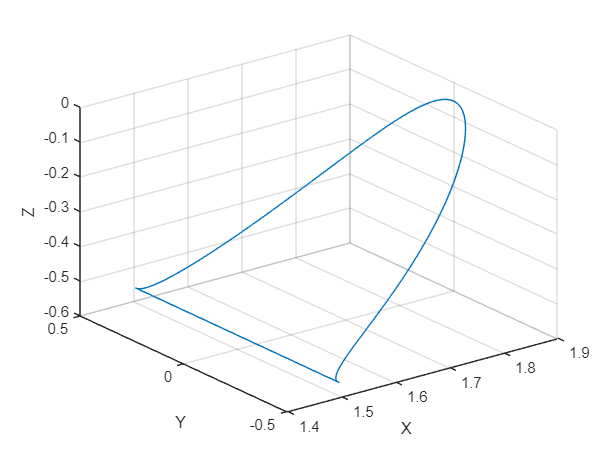



figure;
title('Trajectory');
plot3(x_leg(:,2),y_leg(:,2),z_leg(:,2));
xlabel('X');  
ylabel('Y');
zlabel('Z');
grid on;

## Построение траектории движения центра масс корпуса робота

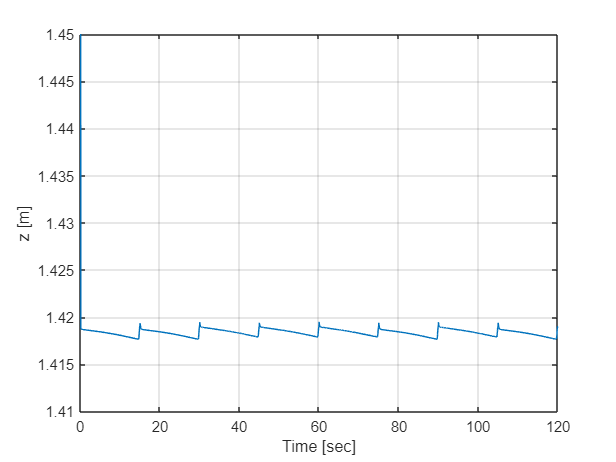



simOut = sim('My_hexapod');

figure;
title('Trajectory');
plot(simOut.xyz.Z.Time, simOut.xyz.Z.Data);
grid on;
xlabel('Time [sec]');  
ylabel('z [m]');
ylim([1.41 1.45]);

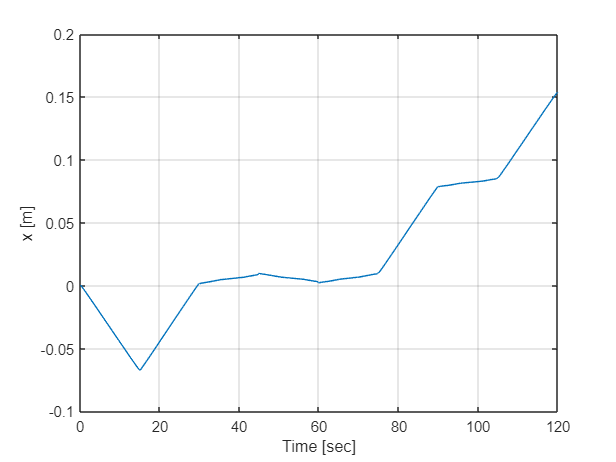


figure;
title('Trajectory');
plot(simOut.xyz.X.Time, simOut.xyz.X.Data);
grid on;
xlabel('Time [sec]');  
ylabel('x [m]');

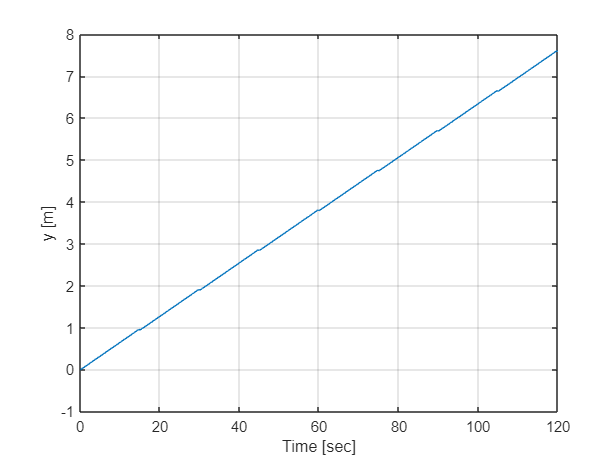


figure;
title('Trajectory');
plot(simOut.xyz.Y.Time, simOut.xyz.Y.Data);
grid on;
xlabel('Time [sec]');  
ylabel('y [m]');